# Analytische und numerische Näherungslösung

### 1. Die Differentialgleichung

Die vollständige Gleichung lautet $\ddot{\varphi} +\frac{g}{l}\sin (\varphi )=0$. Für kleine Auslenkungen gilt die Näherung $\sin (\varphi )\approx \varphi$ (Kleinwinkelnäherung). Die zu lösende homogene lineare Differentialgleichung 2. Ordnung lautet:


$$\ddot{\varphi} (t)+\frac{g}{l}\varphi (t)=0$$


### 2. Ansatz über charakteristisches Polynom

Wir wählen den Exponentialansatz $\varphi (t)=e^{\lambda t}$. Einsetzen ergibt:


$$\lambda^2 e^{\lambda t} +\frac{g}{l}e^{\lambda t} =0$$


Da $e^{\lambda t} \not= 0$, muss gelten:


$$\lambda^2 +\frac{g}{l}=0\Longrightarrow \lambda^2 =-\frac{g}{l}$$


Daraus ergeben sich die rein imaginären Eigenwerte:


$$\lambda_{1,2} =\pm \sqrt{-\frac{g}{l}}=\pm i\sqrt{\frac{g}{l}}$$


Die allgemeine Lösung ergibt sich aus einer Linearkombination von Sinus und Kosinus:


$$\varphi (t)=C_1 \cos \left(\sqrt{\frac{g}{l}}t\right)+C_2 \sin \left(\sqrt{\frac{g}{l}}t\right)$$


### 3. Anfangswertproblem

Wir nehmen typische Anfangsbedingungen an:

- Startwinkel: $\varphi (0)=\varphi_0$ (Auslenkung)

- Startgeschwindigkeit: $\dot{\varphi} (0)=0$ (Loslassen aus Ruhe)

**Berechnung von** $C_1$**:**


$$\varphi (0)=C_1 \cos (0)+C_2 \sin (0)=C_1 \cdot 1+0=\varphi_0 \Longrightarrow C_1 =\varphi_0$$


**Berechnung von** $C_2$**:**Wir leiten die allgemeine Lösung ab (unter Beachtung der Kettenregel):


$$\dot{\varphi} (t)=-C_1 \sqrt{\frac{g}{l}}\sin \left(\sqrt{\frac{g}{l}}t\right)+C_2 \sqrt{\frac{g}{l}}\cos \left(\sqrt{\frac{g}{l}}t\right)$$


Einsetzen von $t=0$:


$$0=-C_1 \sqrt{\frac{g}{l}}\cdot 0+C_2 \sqrt{\frac{g}{l}}\cdot 1\Longrightarrow C_2 =0$$


### 4. Endergebnis und physikalische Interpretation

Die analytische Lösung für das Auslenken und Loslassen lautet:


$$\varphi (t)=\varphi_0 \cos \left(\sqrt{\frac{g}{l}}\cdot t\right)$$


**Bestimmung von Kreisfrequenz und Periodendauer**

Vergleicht man dies mit der allgemeinen Schwingungsgleichung $\varphi (t)=\varphi_0 \cos (\omega t)$, so identifizieren wir die **Eigenkreisfrequenz**:


$$\omega =\sqrt{\frac{g}{l}}$$


Daraus lässt sich nun die **Periodendauer** $T$ (die Zeit für eine vollständige Hin- und Herschwingung) berechnen:


$$T=\frac{2\pi }{\omega }=\frac{2\pi }{\sqrt{\frac{g}{l}}}$$


Durch Umformen erhalten wir die bekannte Formel für die Schwingungsdauer des Fadenpendels:


$$T=2\pi \sqrt{\frac{l}{g}}$$


Einsetzen der Werte:

T = 2 * pi / sqrt(0.1);
fprintf('Periodendauer T:        %.4f s\n', T);

Periodendauer T:        19.8692 s


**Ergebnis:** Die Periodendauer $T$ beträgt in der harmonischen Näherung ca. **19,87 Sekunden**.

### Numerische Lösung der Näherung

Für die numerische Lösung in MATLAB überführen wir die DGL 2. Ordnung in ein System von zwei DGLs 1. Ordnung.

Substitution: $y_1 =\varphi$ (Winkel) $y_2 =\dot{\varphi}$ (Winkelgeschwindigkeit)

Ableitungen: ${\dot{y} }_1 =y_2 \;;{\dot{y} }_2 =\ddot{\varphi} =-\frac{g}{l}\varphi =-0,1\cdot y_1$

clear; clc; close;

% --- Parameter ---
g_l = 0.1;          % g/l in s^-2
t_end = 100;        % Simulationszeit in s (gross genug fuer > 2 Perioden)
phi0 = 0.1;         % Kleine Anfangsauslenkung (z.B. 0.1 rad)
w0 = 0;             % Anfangsgeschwindigkeit

% --- Numerische Loesung (ode45) ---
% Wir rufen die lokale Funktion 'linear_pendulum_ode' auf, die unten definiert ist.
% Wir uebergeben g_l als Parameter.
[t, y] = ode45(@(t,y) linear_pendulum_ode(t, y, g_l), [0 t_end], [phi0; w0]);

% Extrahieren der Ergebnisse
phi_num = y(:, 1);

% --- Bestimmung der Periodendauer T aus der Simulation ---
% Wir suchen die Zeitpunkte der Nulldurchgaenge oder Peaks.
% Suche nach Peaks (Maxima), um T als Differenz zu berechnen.
[pks, locs] = findpeaks(phi_num, t);

if length(locs) >= 2
    T_numerisch = mean(diff(locs));
    fprintf('Numerisch ermittelte Periodendauer T: %.4f s\n', T_numerisch);
else
    fprintf('Nicht genuegend Perioden simuliert fuer T-Bestimmung.\n');
end

Numerisch ermittelte Periodendauer T: 19.8688 s



% Analytischer Vergleichswert
T_analytisch = 2*pi/sqrt(g_l);
fprintf('Analytische Periodendauer T:        %.4f s\n', T_analytisch);

Analytische Periodendauer T:        19.8692 s


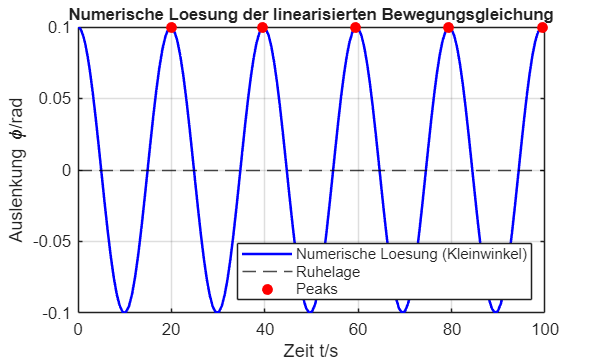


% --- Visualisierung ---
figure;
plot(t, phi_num, 'b-', 'LineWidth', 1.5);
hold on;
yline(0, 'k--');
xlabel('Zeit t/s');
ylabel('Auslenkung \phi/rad');
title('Numerische Loesung der linearisierten Bewegungsgleichung', 'FontSize', 10);
grid on;

% Markiere die Peaks zur Veranschaulichung
plot(locs, pks, 'ro', 'MarkerFaceColor', 'r');

legend('Numerische Loesung (Kleinwinkel)', 'Ruhelage', 'Peaks','Location','southeast');


% ---------------------------------------------------------
% Lokale Funktionen
% ---------------------------------------------------------

function dydt = linear_pendulum_ode(~, y, g_l)
    % Diese Funktion definiert die DGL fuer das linearisierte Pendel.
    % Eingabe:
    %   t   - Zeit (wird hier nicht explizit genutzt, da autonomes System)
    %   y   - Zustandsvektor [Winkel phi; Winkelgeschwindigkeit omega]
    %   g_l - Parameter g/l
    % Ausgabe:
    %   dydt - Ableitung des Zustandsvektors
    
    phi = y(1);
    omega = y(2);
    
    % DGL: phi'' + (g/l)*phi = 0  =>  phi'' = -(g/l)*phi
    dphi_dt = omega;
    domega_dt = -g_l * phi;
    
    dydt = [dphi_dt; domega_dt];
end